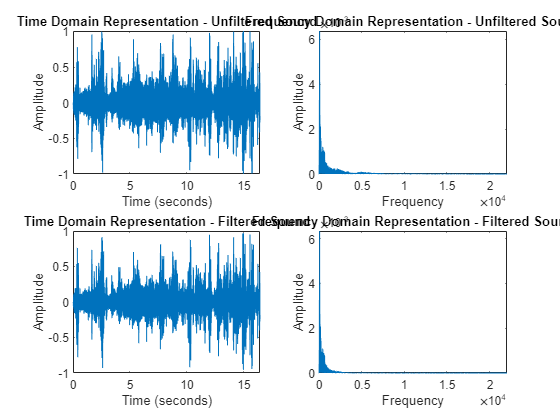

clc
clear


%%1) Load the 'audio_sample.wav' file in MATLAB
[sample_data, sample_rate] = audioread('testaudio.ogg');

%% Plot the original signal in time domain
% components using the FFT.
sample_period = 1/sample_rate;
t = (0:sample_period:(length(sample_data)-1)/sample_rate);
subplot(2,2,1)
plot(t,sample_data)
title('Time Domain Representation - Unfiltered Sound')
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t(end)])


m = length(sample_data); % Original sample length.
n = pow2(nextpow2(m)); % Transforming the length so that the number of
% samples is a power of 2. This can make the transform computation
% significantly faster, particularly for sample sizes with large prime
% factors.


%% Plot the original signal in frequency domain
y = fft(sample_data, n);
f = (0:n-1)*(sample_rate/n);
amplitude = abs(y)/n;
subplot(2,2,2)
plot(f(1:floor(n/2)),amplitude(1:floor(n/2)))
title('Frequency Domain Representation - Unfiltered Sound')
xlabel('Frequency')
ylabel('Amplitude')


%% Filter the audio file with low pass butterworth filter and listen it 
% sound(sample_data, sample_rate)
%%2) Filter the audio sample data to remove noise from the signal.

df = designfilt('lowpassfir', 'FilterOrder', 100, 'CutoffFrequency', 50, 'Samplerate', 500, 'Window', 'hamming');
y = filter(df, sample_data);
sound(y, sample_rate)




%% Plot the filtered audio file in time domain
t1 = (0:sample_period:(length(filtered_sound)-1)/sample_rate);
subplot(2,2,3)
plot(t1,filtered_sound)
title('Time Domain Representation - Filtered Sound')
xlabel('Time (seconds)')
ylabel('Amplitude')
xlim([0 t1(end)])
m1 = length(sample_data); % Original sample length.
n1 = pow2(nextpow2(m1)); % Transforming the length so that the number of
% samples is a power of 2. This can make the transform computation
% significantly faster, particularly for sample sizes with large prime
% factors.
%% Plot the filtered audio file in frequency domain
y1 = fft(filtered_sound, n1);
f = (0:n1-1)*(sample_rate/n1);
amplitude = abs(y1)/n1;
subplot(2,2,4)
plot(f(1:floor(n1/2)),amplitude(1:floor(n1/2)))
title('Frequency Domain Representation - Filtered Sound')
xlabel('Frequency')
ylabel('Amplitude')